clear
close all

syms a b c m n p real positive
syms t real
syms x(t) y(t)


% ode1 = diff(x,t) == a*x -b*x*y
% ode2 = diff(y,t) == m*y - n*x*y


ode1 = diff(x,t) == -a*x +b*x*y

$$ode1(t) = \frac{\partial }{\partial t}x\left(t\right)=b\,x\left(t\right)\,y\left(t\right)-a\,x\left(t\right)$$

ode2 = diff(y,t) == -m*y + n*x*y

$$ode2(t) = \frac{\partial }{\partial t}y\left(t\right)=n\,x\left(t\right)\,y\left(t\right)-m\,y\left(t\right)$$

odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=b\,x\left(t\right)\,y\left(t\right)-a\,x\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)=n\,x\left(t\right)\,y\left(t\right)-m\,y\left(t\right) \end{array}\right)$$

a0 = 2

a0 = 2

b0 = 1

b0 = 1

c0 = 1

c0 = 1

m0 = 3

m0 = 3

n0 = 1

n0 = 1

p0 = 1

p0 = 1

odes1 = subs(odes, [a b c m n p], [a0 b0 c0 m0 n0 p0])

$$odes1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=x\left(t\right)\,y\left(t\right)-2\,x\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)=x\left(t\right)\,y\left(t\right)-3\,y\left(t\right) \end{array}\right)$$

V = odeToVectorField(odes1)

$$V = \left(\begin{array}{c} Y_{1}\,Y_{2}-3\,Y_{1}\\ Y_{1}\,Y_{2}-2\,Y_{2} \end{array}\right)$$

Yode = matlabFunction(V, 'vars', {'t','Y'})

Yode = 包含以下值的 function_handle :
    @(t,Y)[Y(1).*-3.0+Y(1).*Y(2);Y(2).*-2.0+Y(1).*Y(2)]


tspan = [0 3];
x0 = 10;
y0 = 1;

[t,Y] = ode45(Yode, tspan, [x0;y0])

t =          0
    0.0063
    0.0126
    0.0188
    0.0251
    0.0521
    0.0791
    0.1061
    0.1331
    0.1667


Y = 	1.0e+15 *

    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


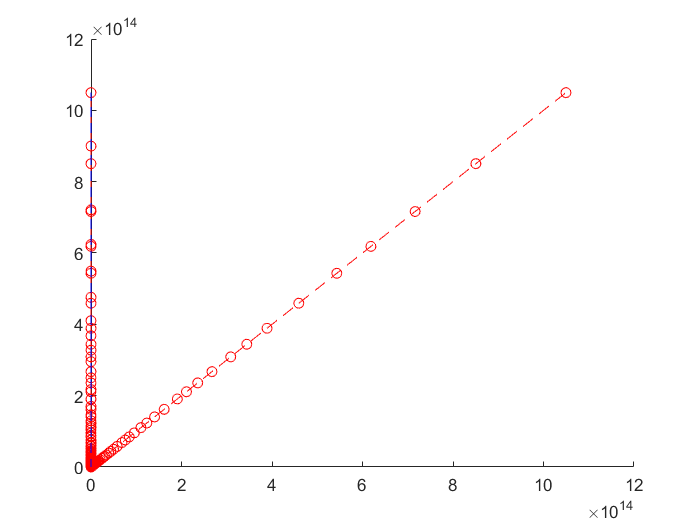

plot(t,Y(:,1), '-ro', t,Y(:,2), '--b')

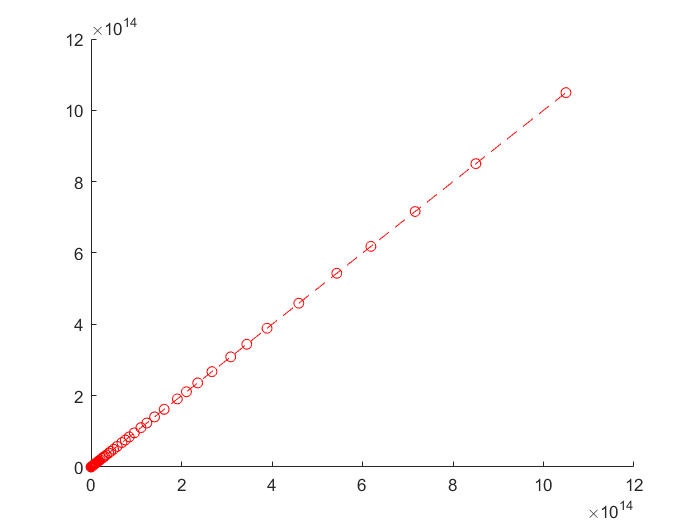

figure
hold on
plot(Y(:,1),Y(:,2),'--ro')